#  Sistemas Realimentados - Trabalho 1 

Nome: Gabrielly Barcelos Cariman

**Data limite para entrega:14/9, meia-noite**.

**Referências para este trabalho além das notas de aula:**

- [Manual rápido do Matlab](https://drive.google.com/file/d/1_mXyft7ynFmkxGnCyx7BV8VyOKyIx9tj/view?usp=share_link)

- [Resposta transitória e estacionária](https://drive.google.com/file/d/19GToHEkcvTon0UK2nOmi1_l0k5dx3YIJ/view?usp=share_link)

**Inicialização:**

I=14; % Seu valor de I
[Y,G1,G2]=init_t1(I);
datetime('now')
warning off

**I) Relação entre resposta ao degrau e modelos**

Observe nas figura 1,2,3 a resposta ao degrau unitário dos modelos g1, g2, g3.

figure;plot(Y(1).t,Y(1).y);title('Fig1 - Resposta de g1');xlabel('Tempo(s)');
figure;plot(Y(2).t,Y(2).y);title('Fig2 - Resposta de g2');xlabel('Tempo(s)');
figure;plot(Y(3).t,Y(3).y);title('Fig3 - Resposta de g3');xlabel('Tempo(s)');

ans = datetime
   15-Sep-2023 01:40:56


1) Obtenha os modelos g1,g2,g3 que geraram estas respostas ao degrau, defina-os abaixo e compare com as curvas fornecidas usando os comandos dados.

Resposta:

O sistema G1 pode ser descrito como um sistema de primeira ordem com tempo morto. Uma análise detalhada do Gráfico 1 revela que o tempo morto é aproximadamente 13 segundos. Além disso, é perceptível que o valor de regime é cerca de 1,1.

A constante de tempo, denotada por T, é definida como o tempo necessário para que a saída atinja 63% do valor de regime, ou seja, aproximadamente 0,7. Portanto, observando o gráfico, podemos identificar que quando y atinge 0,7, o tempo é aproximadamente 41 segundos. Nesse momento, a saída alcançou cerca de 63% do valor de regime, mas é importante notar que ela começou a mudar somente após 13 segundos.

Consequentemente, podemos calcular a constante de tempo T da seguinte maneira: T = 41 s - 13 s = 28 segundos. O tempo morto permanece como 13 segundos.

A equação para um sistema de primeira orderm com tempo morto é da seguinte forma:


$$G(s) = \frac{K\cdot e^{-ds}}{\tau s + 1}$$


Em que:

K é o ganho

 $d$ é o tempo morto

 $\tau$ é a constante de tempo 

Como já foi descrito antes, obtivemos os seguintes valores:

K: 1,1

 $d$: 13 segundos

 $\tau$: 28 segundos

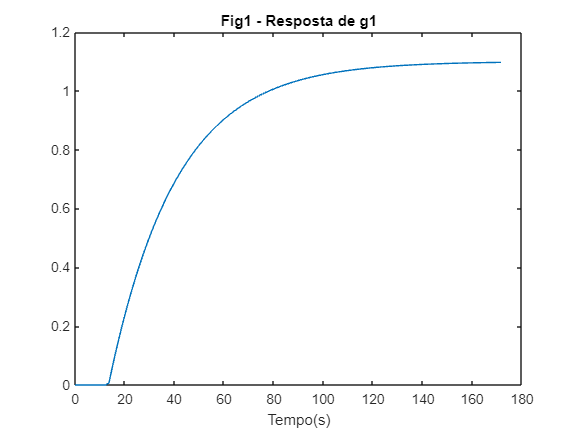

d1 = 13;
k1 = 1.1;
saida1 = 0.632 * k1; % saida1 = 0.6952
tau1 = 41 - d1; % tau1 = 28


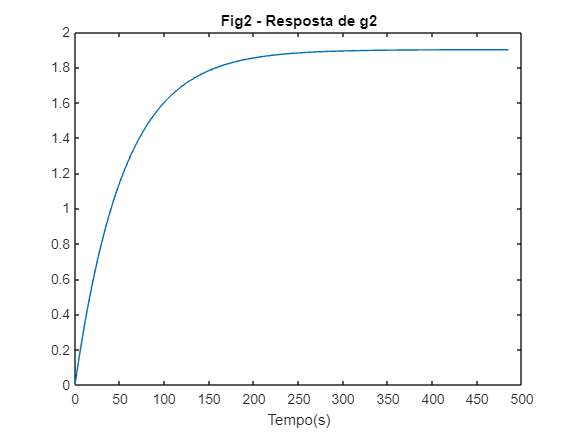

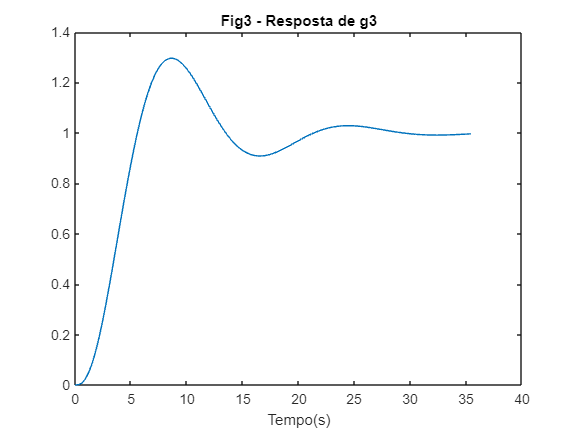

s=tf('s');

g1 = (k1 * exp(-d1*s))/(tau1*s + 1)

O sistema G2 pode ser descrito como um sistema de primeira ordem. É perceptível que o valor de regime é cerca de 1,9.

A constante de tempo, denotada por T, é definida como o tempo necessário para que a saída atinja 63% do valor de regime, ou seja, aproximadamente 1,2. Portanto, observando o gráfico, podemos identificar que quando y atinge 1,2, o tempo é aproximadamente 54 segundos.

Consequentemente, a constante de tempo T é: T = 54 segundos.

A equação para um sistema de primeira orderm sem tempo morto é da seguinte forma:


$$G(s) = \frac{K}{\tau s + 1}$$


Em que:

K é o ganho

 $\tau$ é a constante de tempo 

Como já foi descrito antes, obtivemos os seguintes valores:

K: 1,9

 $\tau$: 54 segundos

k2 = 1.9;
saida2 = 0.632 * k2; % saida2 = 1.2008
tau2 = 54;
g2 = (k2)/(tau2*s + 1)

O máximo sobressinal, Mp, é o valor máximo de pico da curva de resposta em relação ao valor de regime. Para G3 temos aproximadamente que:

- Mp = 33 % = 0.33

O amortecimento é dado por:


$$\zeta = \frac{ln^2(M_{P})}{\sqrt{\pi^2 + ln^{2}(M_{p})}}$$


Com isso, obtemos $\zeta  = $ 0,3689

Para o tempo de estabelecimento ts de aproximadamente 27 segundos observado no gráfico, considerando 2%, obtemos $w_n$ da seguinte forma:


$$w_{n} = \frac{4}{\zeta t_s}$$


A equação para um sistema de segunda orderm é da seguinte forma:


$$G(s) = \frac{w_{n}^{2}}{s^2 + 2 \zeta w_{n} s + w_{n}^{2}}$$


Obtivemos os seguintes valores:

$w_n$ = 0,4015

$\zeta = $ 0,3689

Como os valores de Mp e ts foram selecionados apenas com base em observação do gráfico, eles são valores aproximados.

Por isso, o gráfico gerado a partir desses valores não é exatamente igual ao gráfico real, mas sim uma aproximação com algum erro.

Mp = 33/100; % Mp = 33% = 0.33
zeta = (log(Mp)^2)/(sqrt(pi^2 + (log(Mp)^2))); % zeta = 0.3689
ts = 27;

g1 =
 
                 1.1
  exp(-13*s) * --------
               28 s + 1
 
Continuous-time transfer function.
Model Properties


w_n = 4/(zeta*ts); % w_n = 0.4015
g3 = (w_n^2) / ((s^2) + (2*zeta*w_n*s) + (w_n^2))
y1=step(g1,Y(1).t);
y2=step(g2,Y(2).t);
y3=step(g3,Y(3).t);
figure;plot(Y(1).t,Y(1).y,Y(1).t,y1);title('Fig4 - Resposta de g1 e modelo obtido');
figure;plot(Y(2).t,Y(2).y,Y(2).t,y2);title('Fig5 - Resposta de g2 e modelo obtido');
figure;plot(Y(3).t,Y(3).y,Y(3).t,y3);title('Fig6 - Resposta de g3 e modelo obtido');

**II) Desempenho em função do ganho K**. 

Seja a função de transferência G1 já definida.

Os comandos abaixo permitem obter os vários parâmetros de desempenho em malha fechada quando o ganho K varia. **Escolha kmax **de modo que todos gráficos mostrem claramente o efeito do ganho em cada parâmetro. Sugestão: escolha kmax de modo que UP vá de 0 a 60%.

kmax=60; % Escolher valor adequado para kmax
up=[];ts=[];iae=[];erro=[];
K=linspace(0,kmax,20);
for i=1:length(K)

g2 =
 
    1.9
  --------
  54 s + 1
 
Continuous-time transfer function.
Model Properties


    m=feedback(K(i)*G1,1);
    S=stepinfo(m);
    [y,t]=step(m);
    up=[up;S.Overshoot];
    ts=[ts;S.SettlingTime];
    iae=[iae;trapz(t,abs(1-y))];
    erro=[erro;1-y(end)];
end
figure;
subplot(4,1,1);bar(K,up);title('Fig.7 - UP');
subplot(4,1,2);bar(K,ts);title('Tempo de estabelecimento');
subplot(4,1,3);bar(K,iae);title('IAE');
subplot(4,1,4);bar(K,erro);title('Erro em regime');xlabel('Ganho K');

2.1 Escolha o ganho K para o qual considera que houve uma boa resposta, informando o ganho K, UP, ts, IAE e o erro em regime correspondentes.

Acredito que um ganho de aproximadamente 9 proporciona uma boa resposta. Isso se deve ao fato de que esse valor resulta em aproximadamente UP de 36, tempo de estabilização (ts) de 310 s, IAE de 73 e um erro em regime de zero. Assim, esse ganho consegue minimizar o erro em regime, mantendo valores aceitáveis para UP e IAE, além de garantir um tempo de estabelecimento bastante razoável. Dessa forma, obtemos uma resposta satisfatória com pouca oscilação, rápida estabilização e um nível de erro em relação à referência aceitável.

É importante ressaltar que a escolha desse ganho representa um valor intermediário. Um ganho muito baixo, próximo de zero, seria inviável devido ao erro em regime extremamente elevado. Por outro lado, um ganho muito alto, como 60 por exemplo, não seria uma opção adequada, já que, apesar de apresentar um erro em regime e um IAE baixos, o valor de UP seria excessivamente grande.

2.2 Feche a malha com este ganho K, obtenha os polos de malha fechada e mostre que a resposta ao degrau é a especificada.

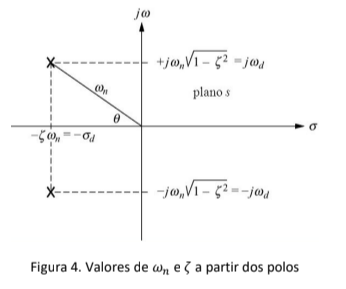

Como a parte real dos polos é negativa, sendo - 0.0111 + 0.0334i e - 0.0111 - 0.0334i os polos, isso mostra que o sistema é estável. Assim com também e possível ver no gráfico. 

K = 9;
m01 = feedback(G1*K, 1)
polos = pole(m01)
figure;
rlocus(m01);

g3 =
 
          0.1612
  -----------------------
  s^2 + 0.2963 s + 0.1612
 
Continuous-time transfer function.
Model Properties


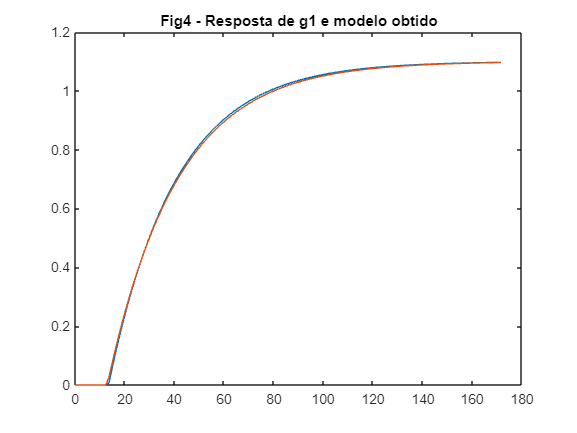

title('Fig8 - Polos de malha fechada');
figure;
step(m01);
title(['Fig9 - Resposta ao degrau para K = ', num2str(K)]);

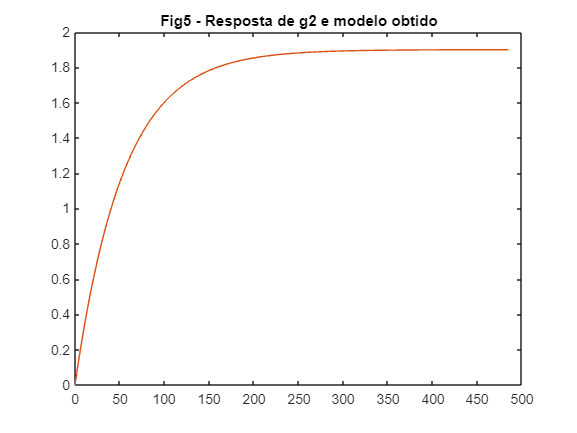

S = stepinfo(m01);

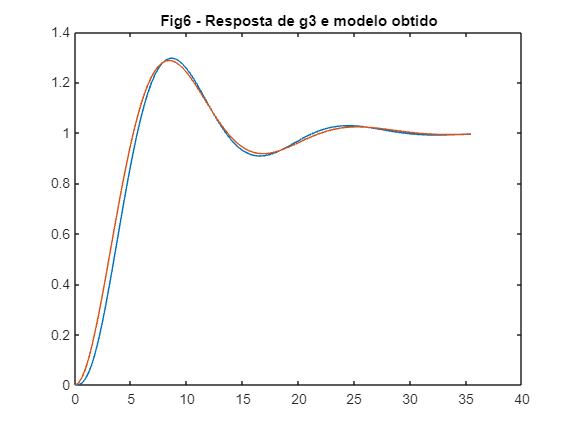

[y,t]=step(m01);

up = S.Overshoot
ts = S.SettlingTime
iae = trapz(t,abs(1-y))
erro = 1-y(end)

Conforme mencionado previamente, a parte real dos polos é negativa, indicando a estabilidade do sistema, conforme evidenciado no gráfico apresentado.

Além disso, ao analisarmos o gráfico e os valores obtidos pela função stepinfo, observamos que o sobressinal é de aproximadamente 35%, o que coincide com a informação na figura 7, que apresenta um sobressinal de cerca de 36%. Adicionalmente, o tempo de estabilização calculado a partir do gráfico é de aproximadamente 317 segundos, em consonância com o tempo de estabilização indicado na figura 7, que é de 310 segundos. Outro ponto é que o IAE calculado a partir do gráfico acima é de 74, o que é muito próximo do IAE na figura 7, que é de 73. Notamos que o erro em regime permanente do valor calculado pela função é de 0,0548, o que está muito próximo do valor na figura 7, de aproximadamente 0,05365 que está muito próximo de zero. Isso confirma que a resposta ao degrau é a especificada.

2.3 Calcule à mão o erro em regime usando G1 e o ganho K selecionado em 2.1, e compare com o valor obtido no gráfico na Fig7.

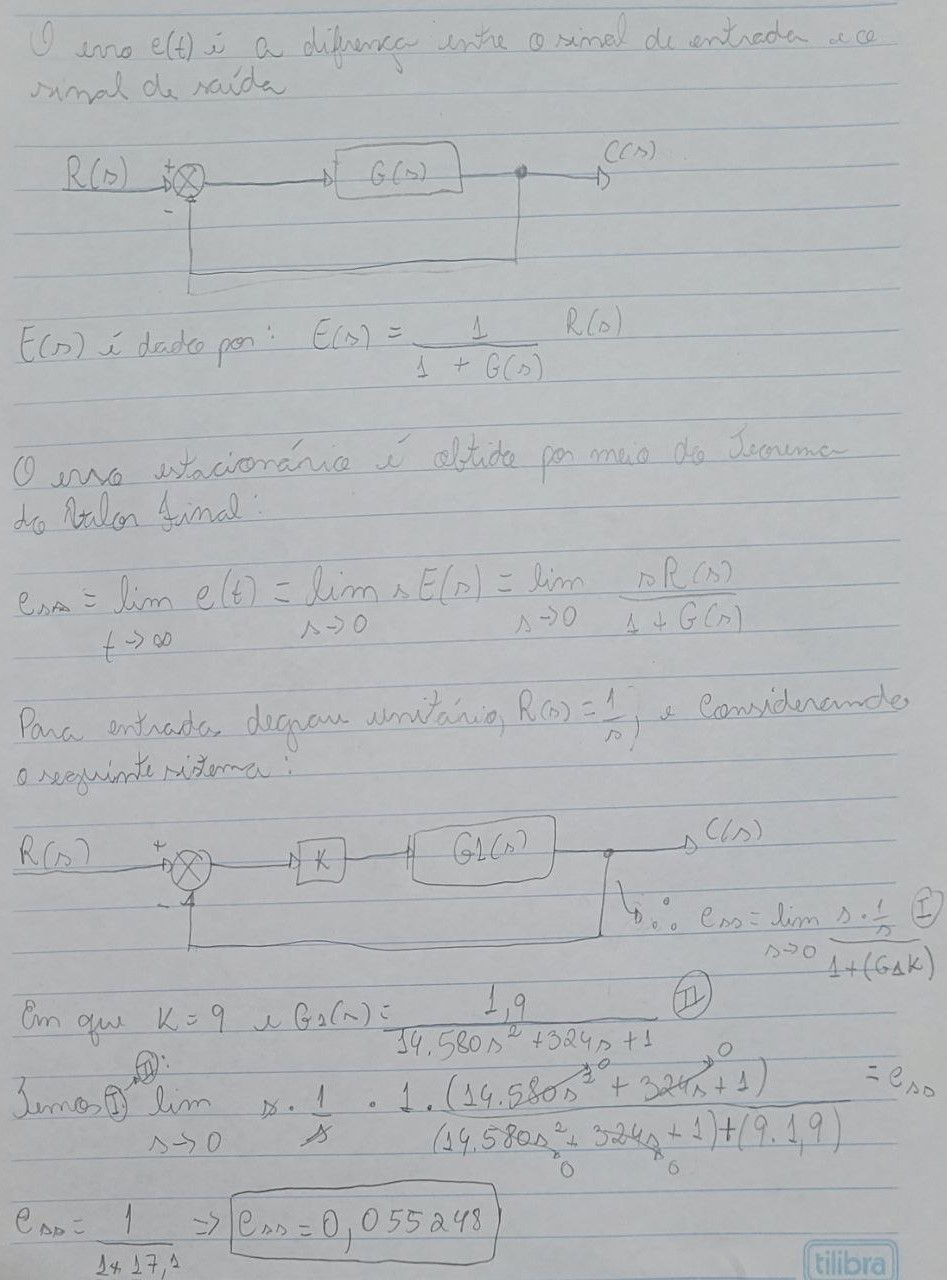

G1

O erro em regime foi calculado manualmente usando G1, e o ganho K de 9 resultou em 0.055248. Este valor é muito próximo ao obtido no gráfico da Figura 7, que é 0.05365. Ambos os valores são muito próximos de zero, indicando que o erro em regime quando o ganho é 9 é aproximadamente zero.

**III) Projeto de controlador PID via métodos de sintonia baseados na resposta ao degrau**

Use o método de sintonia Ziegler-Nichols e projete controladores C(s) da forma P, PI e PID para G2 já definida.

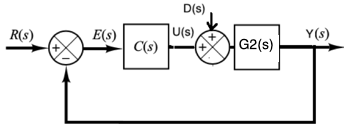

3.1) Compare a resposta ao degrau Y(s)/R(s) de cada controlador em termos de UP, ts, erro em regime, plotando a resposta de P,PI,PID na mesma figura.

G2
[cp, iaep] = pidtuning(G2, 'method', 'zie', 'type', 'P');
[cpi, iaepi] = pidtuning(G2, 'method', 'zie', 'type', 'PI');
G2_pade = pade(G2, 2);
[cpid, iaepid] = pidtuning(G2, 'method', 'zie', 'type', 'PID');

mcp = feedback(cp*G2, 1);
mcpi = feedback(cpi*G2, 1);
mcpid = feedback(cpid*G2_pade, 1);
step(mcp, mcpi, mcpid);
title('Fig10 - Resposta ao degrau de cada controlador');
legend('P', 'PI', 'PID');shg

Resposta ao degrau do controlador P em termos de UP, ts, erro em regime:

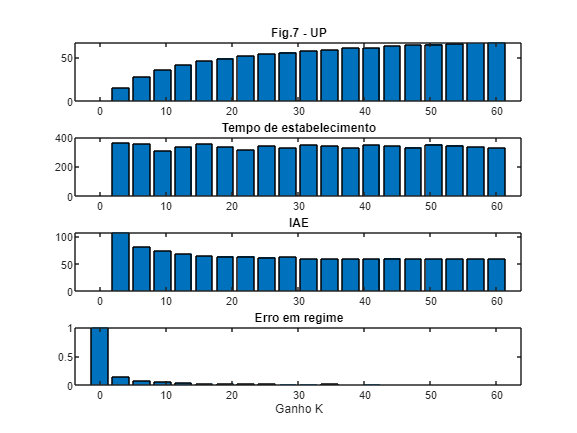

Scp = stepinfo(mcp);
[ycp,tcp]=step(mcp);
upcp = Scp.Overshoot
tscp = Scp.SettlingTime

iaep
errocp = 1-ycp(end)

UP: 43%, ts: 90.5 s, erro em regime: 0.34

Resposta ao degrau do controlador PI em termos de UP, ts, erro em regime:

Scpi = stepinfo(mcpi);
[ycpi,tcpi]=step(mcpi);

m01 =
 
            17.1
  ------------------------
  14580 s^2 + 324 s + 18.1
 
Continuous-time transfer function.
Model Properties


upcpi = Scpi.Overshoot

polos =   -0.0111 + 0.0334i
  -0.0111 - 0.0334i


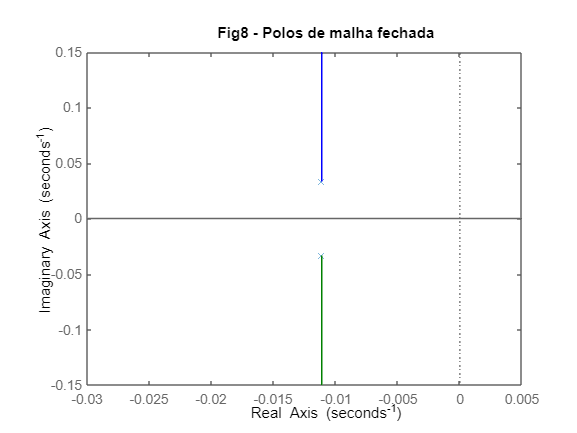

tscpi = Scpi.SettlingTime
iaepi
errocpi = 1-ycpi(end)

UP: 17.67%, ts: 107.75 s, erro em regime: 0

Resposta ao degrau do controlador PID em termos de UP, ts, erro em regime:

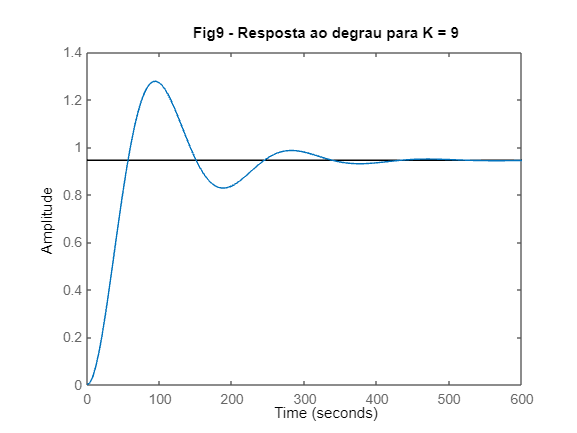

Scpid = stepinfo(mcpid);
[ycpid,tcpid]=step(mcpid);
upcpid = Scpid.Overshoot

tscpid = Scpid.SettlingTime
iaepid
errocpid = 1-ycpid(end)

up = 35.1645

UP: 31.02%, ts: 68.08 s, erro em regime: 0

Como já foi apresentado, obtivemos as seguintes respostas:

- Resposta ao degrau do controlador P: UP: 43%, ts: 90.5 s, erro em regime: 0.34

- Resposta ao degrau do controlador PI: UP: 17.67%, ts: 107.75 s, erro em regime: 0

- Resposta ao degrau do controlador PID: UP: 31.02%, ts: 68.08 s, erro em regime: 0

É evidente que o controlador P oferece o desempenho mais fraco devido ao alto erro em regime permanente, algo que deve ser evitado. Portanto, a escolha do melhor controlador recai entre o controlador PI, que possui o menor valor de UP, apesar de apresentar um tempo de estabilização, ts, considerável. Por outro lado, o controlador PID exibe um valor de UP maior que o PI e é mais oscilatório, mas ostenta um tempo de estabilização menor. Ambos, no entanto, apresentam erro em regime permanente de aproximadamente zero. Dessa forma, a decisão se resume a escolher entre um controlador mais rápido, que terá um sobressinal maior e será mais oscilatório, ou um mais lento com um sobressinal menor. Ambas as opções têm suas vantagens e desvantagens. Contudo, ambas têm a vantagem de ter um erro em regime permanente de aproximadamente zero.

3.2) Compare a resposta a um distúrbio Y(s)/D(s) de cada controlador, verificando qual faz a melhor rejeição ao distúrbio, plotando a resposta de P,PI,PID na mesma figura.

mdcp = feedback(G2, cp);

ts = 317.4440

mdcpi = feedback(G2, cpi);

iae = 74.6437

mdcpid = feedback(G2, cpid);

erro = 0.0548

step(mdcp, mdcpi, mdcpid);
title('Fig11 - Resposta a um distúrbio de cada controlador');
legend('P', 'PI', 'PID');shg;

Estamos analisando a resposta de cada controlador a um distúrbio. Portanto, o melhor controlador será aquele que proporciona a melhor rejeição ao distúrbio, ou seja, o valor em regime precisa ser zero.

De imediato, observamos que o controlador P tem novamente o pior desempenho, devido ao seu alto erro em regime, resultando em um valor de aproximadamente 0.47, ao invés de zero, em regime.

Além disso, notamos que os controladores PI e PID apresentam erro em regime zero. Observamos que o tempo de estabelecimento e o sobressinal do controlador PI são maiores do que os do controlador PID.

Portanto, apesar de o controlador PID ser mais oscilatório que o PI, acredito que ele proporciona a melhor rejeição aos distúrbios, devido ao seu tempo de estabelecimento menor e menor valor de UP. 

**IV) Projeto de controlador PID via métodos de sintonia baseados em modelo**

**Projeto com G2:**

4.1) Seja o modelo G2(s) já definido. Plote em uma mesma figura a resposta ao degrau de G2(s) e de um modelo de referência T(s) que dê a resposta desejada em malha fechada para este processo, de forma que seja mais rápido e sem erro em regime.

G2

G1 =
 
           1.9
  ---------------------
  14580 s^2 + 324 s + 1
 
Continuous-time transfer function.
Model Properties


O sistema G2 pode ser descrito como um sistema de primeira ordem com tempo morto. A equação para um sistema de primeira orderm com tempo morto é da seguinte forma:


$$G(s) = \frac{K\cdot e^{-ds}}{\tau s + 1}$$


Em que:

K é o ganho

 $d$ é o tempo morto

 $\tau$ é a constante de tempo 

 Analisando a equação de G2, vemos que o tempo morto é 10 segundos. Além disso, o ganho é 1,4. A constante de tempo é de  20 segundos.

Como já foi descrito antes, obtivemos os seguintes valores:

K: 1,4

 $d$: 10 segundos

 $\tau$: 20 segundos

Um modelo de referência T(s) também será um sistema de primeira ordem com tempo morto. O tempo morto nesse caso será de 10 segundos, pois é o menor valor possível para o sistema de referência.

Para que a resposta desejada em malha fechada para esse processo não apresente erro em regime, o ganho K precisa ser igual a 1.

Além disso, para que a resposta em malha fechada seja mais rápida do que a do sistema original, representado por G2, a constante de tempo, $\tau$, precisa ser menor do que a constante de tempo de G2.

No entanto, essa constante de tempo não pode ser muito pequena, nem menor do que o tempo morto, pois isso tornaria o sistema inviável ou excessivamente oscilatório devido à alta velocidade de resposta.

Dessa forma, optaremos por um valor conservador de $\tau$ de G2 - 1, o que resultará em um valor de 19 segundos para $\tau$ de T. Isso tornará a resposta em malha fechada mais rápida.

dG2 = 10;

G2 =
 
                 1.4
  exp(-10*s) * --------
               20 s + 1
 
Continuous-time transfer function.
Model Properties


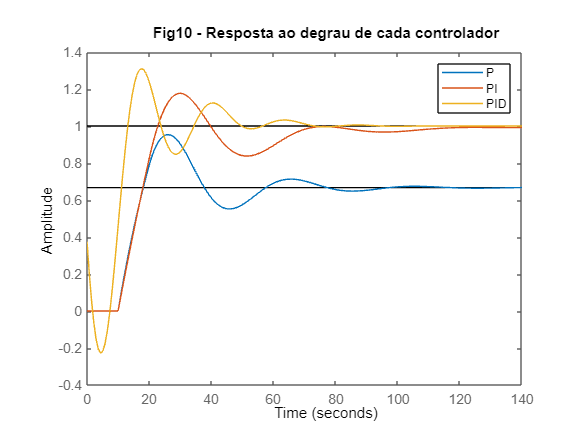

kG2 = 1;
tauG2 = 19;

s=tf('s');

T = (kG2 * exp(-dG2*s))/(tauG2*s + 1)
figure;
step(G2, T);
title('Fig12 - Resposta ao degrau de G2(s) e do modelo de referência T(s)');
legend('G2', 'T');shg
SG2 = stepinfo(G2);

tsG2 = SG2.SettlingTime
ST = stepinfo(T);
tsT = ST.SettlingTime

Como é possível observar no gráfico e calcular a partir da função stepinfo, o modelo de referência T apresenta um tempo de estabelecimento menor em comparação com o G2.

Isto é, enquanto o modelo de referência T tem um tempo de estabelecimento (ts) de aproximadamente 84,33 segundos, o G2 possui um tempo de estabelecimento de cerca de 88,24 segundos. Portanto, o modelo de referência T se estabiliza mais rapidamente do que o G2.

4.2 Explique as escolhas e os cálculos para obter os parâmetros do controlador C(s) pelo método de síntese direta ou IMC. Obtenha os ganhos do controlador C(s) e plote no mesmo gráfico a resposta ao degrau do sistema em malha fechada e do modelo de referência T(s), mostrando o atendimento das especificações.

Resposta:

No Método de Síntese, o controlador resultante depende dos modelos de processos, neste caso é o G2, e do modelo de referência que define o comportamento de malha fechada.

O controlador PID resultante C(s) é tal que $\frac{C\left(s\right)G_2 \left(s\right)}{1+C\left(s\right)G_2 \left(s\right)}=\textrm{Modelo}\;\textrm{de}\;\textrm{Referência}=\frac{1}{\lambda s+1}$

Sendo que $\lambda$ corresponde a constante de tempo, $\tau$, do modelo de referência da resposta em malha fechada.

Portanto, neste caso o $\lambda$ será 19. Para fazer os cálculos pelo método de síntese direta ou IMC utilizando a função pidtuning é necessário apenas passar o modelo em malha aberta G2 e o valor do $\lambda$ definido que é o mesmo valor da constante de tempo, $\tau$, do modelo de referência da resposta em malha fechada.

lambda = tauG2;

upcp = 43.0072

C = pidtuning(G2,lambda);

tscp = 90.4857

C

iaep = 54.6997

O controlador C(s) é um PI, seus ganhos são:

- Kp = 0.94

- Ki = 0.0376

mG2 = feedback(C*G2, 1);

errocp = 0.3364

step(mG2, T);
title('Fig13 - Resposta ao degrau do sistema em malha fechada e do modelo de referência T(s)');
legend('PI', 'T');shg

Resposta ao degrau do controlador C:

S_lambda = stepinfo(mG2);
up_lambda = S_lambda.Overshoot
ts_lambda = S_lambda.SettlingTime

upcpi = 17.6739

[y_lambda,t_lambda]=step(mG2);

tscpi = 107.7485

erro_lambda = 1-y_lambda(end)

iaepi = 22.7469

UP: 6%, ts: 77.85 s, erro em regime: 0

Resposta ao degrau do modelo de referência T:

ST = stepinfo(T);

errocpi = 0.0077

upT = ST.Overshoot
tsT = ST.SettlingTime
[yT,tT]=step(T);
erroT = 1-yT(end)

UP: 0%, ts: 84.33 s, erro em regime: 0

Como já foi apresentado, obtivemos as seguintes respostas:

- Resposta ao degrau do controlador C: UP: 6%, ts: 77.85 s, erro em regime: 0

- Resposta ao degrau do modelo de referência T: UP: 0%, ts: 84.33 s, erro em regime: 0

Como podemos observar no gráfico e nos cálculos, a resposta ao degrau do sistema em malha fechada apresenta um valor extremamente baixo de UP com apenas 6% que pode ser considerado como zero que é o valor da referência, o UP de T.

Além disso, ao analisar o gráfico, percebemos que ambos têm um tempo de estabilização muito próximo, o que é corroborado pelos cálculos. A resposta ao degrau do sistema em malha fechada possui um tempo de estabilização (ts) de 77.85 segundos, enquanto T tem 84.33 segundos, como mencionado anteriormente. Além disso, ambos apresentam erro em regime permanente igual a zero.

Portanto, todas as especificações foram atendidas. A resposta ao degrau do sistema em malha fechada está muito próxima da resposta ao degrau do modelo de referência T. E ambas as respostas são mais rápidas do que o modelo G2 e não possuem erro em regime permanente.

**Projeto com G1:**

4.3 Projete um controlador PID para G1(s) pelo método de síntese direta ou IMC de modo que seu tempo de estabelecimento seja reduzido à metade, com UP<5%.  Plote a saída Y(s) para malha aberta e malha fechada, mostrando o atendimento da especificação, e mostre os valores de UP, ts e IAE.

Resposta:

Primeiro vamos encontrar o tempo de estabelecimento de G1(s):


$$G(s) = \frac{w_{n}^{2}}{s^2 + 2 \zeta w_{n} s + w_{n}^{2}}$$


G1
step(G1)

upcpid = 31.0163

title('Fig14 - Resposta ao degrau de G1');

tscpid = 68.0814

SG1 = stepinfo(G1);

iaepid = 22.1582

tsG1 = SG1.SettlingTime

errocpid = -0.0027

O tempo de estabelecimento de G1(s) é de 1.120 segundos. 

Mas queremos a metade desse tempo de estabelecimento, portanto estamos buscando por um tempo de estabelecimento de 560 segundos.

Agora vamos definir um modelo de referência: $\textrm{Modelo}\;\textrm{de}\;\textrm{Referência}=\frac{1}{\lambda s+1}$ que tenha um tempo de estabelecimento bem parecido

Considerando o modelo de referência um sistema de primeira ordem, temos que o tempo de estabelecimento é aquele necessário para que a saída se aproxime do valor de regime. Nesse caso, pode ser aproximado por 4T.


$$5\tau =560$$


tauG1 = 560/4


$$\tau =140$$


Assim, temos o seguinte modelo de referência:


$$\frac{1}{140s+1}$$


Em que $\lambda$ recebe o valor de 140.

lambdaG1 = tauG1;
[cG1, iaeG1] = pidtuning(G1,lambdaG1)

Saída Y(s) para malha fechada

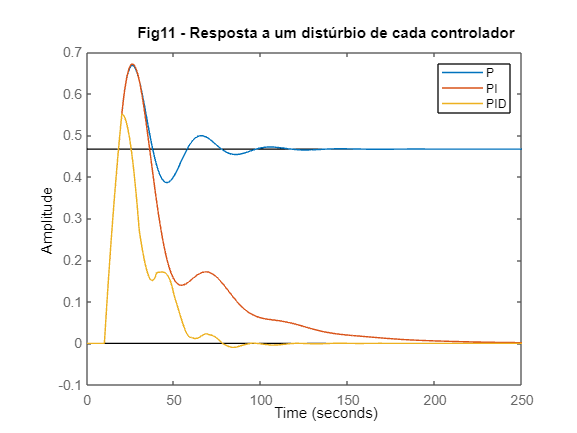

mG1 = feedback(cG1*G1, 1);
step(mG1);
title('Fig15 - Resposta ao degrau da saída Y(s) para malha fechada');

legend('PID');shg
SmG1 = stepinfo(mG1);
upmG1 = SmG1.Overshoot
tsmG1 = SmG1.SettlingTime
iaeG1

Esse foi o projeto de um controlador PID para G1(s) de modo que seu tempo de estabelecimento seja reduzido à metade.

De fato, o tempo de estabelecimento foi reduzido de 1120 segundos para 547.69 segundo, praticamente metade.

UP<5%, porque UP = 0%. Dessa forma, todas as especificações foram atendidas.

Valores de UP, ts e IAE da resposta ao degrau do controlador PID:

- UP = 0%

- ts = 547.69 segundos

- IAE = 132

Como a malha é composta apenas pelo bloco do sistema, G1, e seu controlador, a malha aberta é apenas a multiplicação desses dois sistemas:

step(cG1*G1);

G2 =
 
                 1.4
  exp(-10*s) * --------
               20 s + 1
 
Continuous-time transfer function.
Model Properties


title('Fig16 - Resposta ao degrau da malha aberta com G1 e PID');
legend('Aberta');shg

4.4 Repita para um controlador PI, explicando a diferença de projeto para o controlador PID, bem como a diferença entre os valores de UP, ts e IAE obtidos aqui e em 4.3

Resposta:

Para o projeto do controlador PID usamos a função pidtuning, utilizando o método lambda que é o método de síntese direta ou IMC, informando o lambda que é o valor da constante de tempo, $\tau$, do modelo de referência da resposta em malha fechada.

Porém, esse método não pode ser utilizado para desenvolver um controlador PI para uma função de segunda ordem, como é o caso da G1.

Assim, devemos utilizar o método polealoc que é o método de síntese direta em que fornecemos UP e ts e ele retorna um PI.

Então, informei um UP pequeno de 0.1% e o mesmo ts obtido no item anterior, 547.69 segundos para que a minha resposta obtida seja parecida com a anterior.

G1
UP = 0.1
ts = tsmG1
[cPI, iaePI]=pidtuning(G1,'method','polealoc','type','PI','param',[UP ts])
mPI = feedback(cPI*G1, 1);
SmPI = stepinfo(mPI);
upmPI = SmPI.Overshoot

T =
 
                  1
  exp(-10*s) * --------
               19 s + 1
 
Continuous-time transfer function.
Model Properties


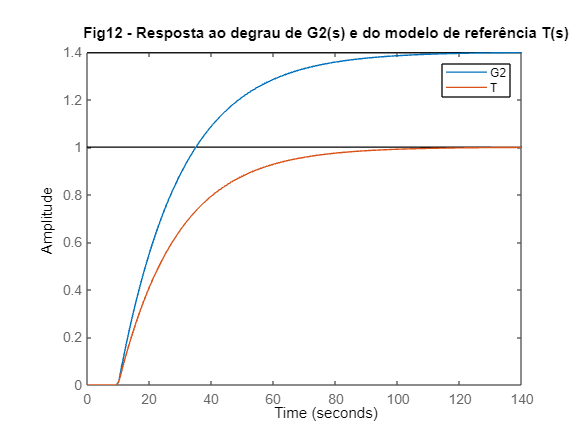

tsmPI = SmPI.SettlingTime
iaePI
step(mPI);
title('Fig17 - Resposta ao degrau de G1 e o PI para malha fechada');

legend('PDI');shg

Esse foi o projeto de um controlador PI para G1(s) de modo que seu tempo de estabelecimento seja reduzido à metade.

De fato, o tempo de estabelecimento foi reduzido de 1120 segundos para 582.43 segundo, praticamente metade.

UP<5%, porque UP = 1.44%. Dessa forma, todas as especificações foram atendidas.

Valores de UP, ts e IAE da resposta ao degrau do controlador PID:

- UP = 1.44%

- ts = 582.43 segundos

- IAE = 234.98

Esse projeto de controlador PI foi projetado de forma diferente do PID porque ele utilizou um método diferente, o polealoc, da mesma função.

Como o método é diferente, ele faz calculos diferentes, tem limitações diferentes e gera um controlador difente. 

O controlador gerado por esse método é um PI e tem ganhos: Kp: 0.556 e Ki: 0.002.

O método anterior gerou um PID que além de ter o ganho Kd de diferente, o ganho Kp era 1.22, bem diferente.

Dessa forma, se não é gerado o mesmo controlador, as respostas serão diferentes  UP, ts e IAE também serão diferentes. 

Malha aberta:

step(cPI*G1);

tsG2 = 88.2438

tsT = 84.3332

C =
 
             1 
  Kp + Ki * ---
             s 

  with Kp = 0.94, Ki = 0.0376
 
Continuous-time PI controller in parallel form.
Model Properties


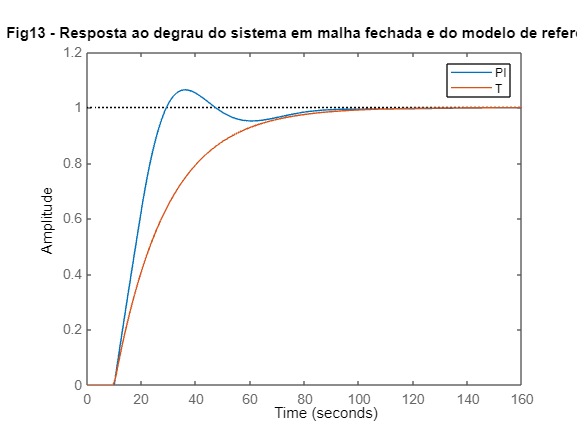

up_lambda = 6.3724

ts_lambda = 77.8510

erro_lambda = 0.0012

upT = 0

tsT = 84.3332

erroT = 0.0051

G1 =
 
           1.9
  ---------------------
  14580 s^2 + 324 s + 1
 
Continuous-time transfer function.
Model Properties


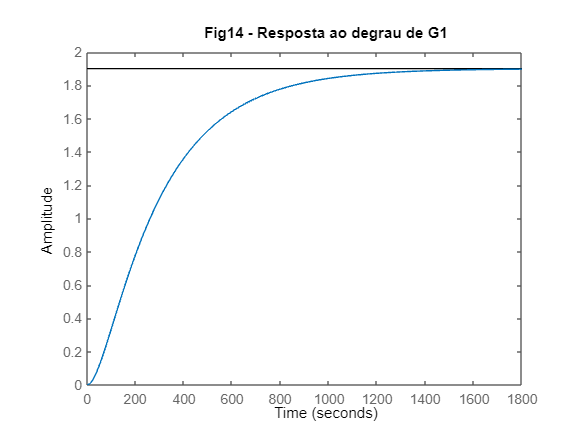

tsG1 = 1.1165e+03

tauG1 = 140

cG1 =
 
             1          
  Kp + Ki * --- + Kd * s
             s          

  with Kp = 1.22, Ki = 0.00376, Kd = 54.8
 
Continuous-time PID controller in parallel form.
Model Properties


iaeG1 = 132.0519

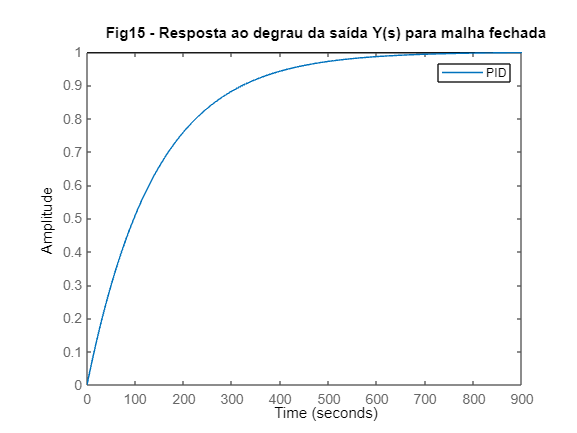

upmG1 = 0

tsmG1 = 547.6904

iaeG1 = 132.0519

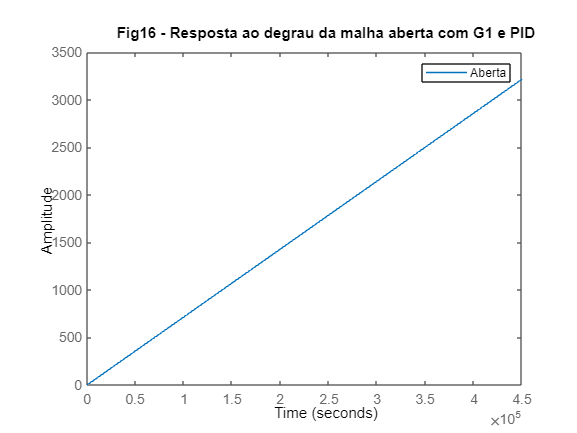

G1 =
 
           1.9
  ---------------------
  14580 s^2 + 324 s + 1
 
Continuous-time transfer function.
Model Properties


UP = 0.1000

ts = 547.6904

cPI =
 
             1 
  Kp + Ki * ---
             s 

  with Kp = 0.556, Ki = 0.00239
 
Continuous-time PI controller in parallel form.
Model Properties


iaePI = 234.9778

upmPI = 1.4407

tsmPI = 582.4259

iaePI = 234.9778

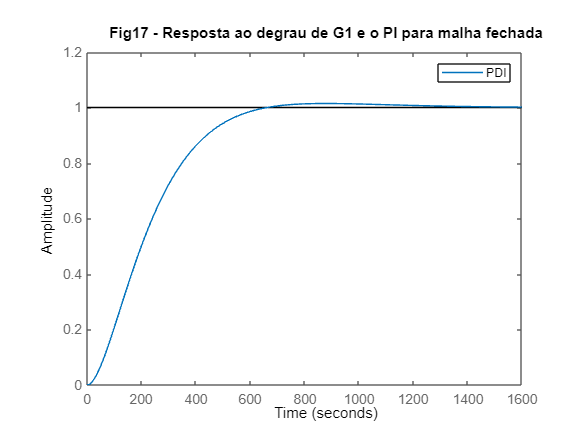

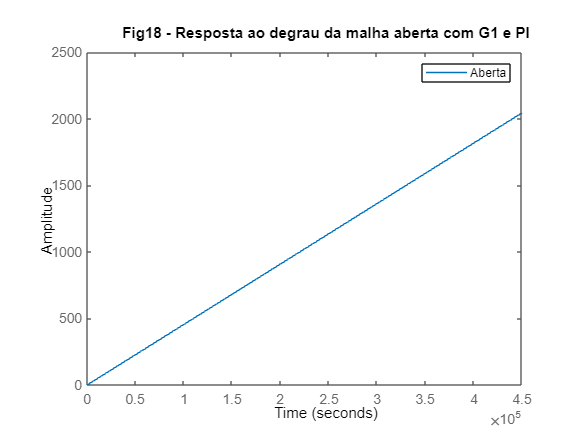

title('Fig18 - Resposta ao degrau da malha aberta com G1 e PI');
legend('Aberta');shg